
InitConfig = struct("AccCode",0x00000000,"AccMask",0xFFFFFFFF,"Reserved",0,"Filter",1,"Timing0",0x01,"Timing1",0x1c,"Mode",0x0)

InitConfig = 包含以下字段的 struct :
     AccCode: 0
     AccMask: 4294967295
    Reserved: 0
      Filter: 1
     Timing0: 1
     Timing1: 28
        Mode: 0


BoardInfo = struct("hw_Version",0x0,"fw_Version",0,"dr_Version",0,"in_Version",0,"irq_Num",0,"can_Num",0,"str_Serial_Num",zeros(1,20),"str_hw_Type",zeros(1,40),"Reserved",zeros(1,4))

BoardInfo = 包含以下字段的 struct :
        hw_Version: 0
        fw_Version: 0
        dr_Version: 0
        in_Version: 0
           irq_Num: 0
           can_Num: 0
    str_Serial_Num: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
       str_hw_Type: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
          Reserved: [0 0 0 0]


CanObj = struct("ID",0x0100,"TimeStamp",0,"TimeFlag",0,"SendType",0,"RemoteFlag",0,"ExternFlag",0,"DataLen",8,"Data",zeros(1,8),"Reserved",zeros(1,3))

CanObj = 包含以下字段的 struct :
            ID: 256
     TimeStamp: 0
      TimeFlag: 0
      SendType: 0
    RemoteFlag: 0
    ExternFlag: 0
       DataLen: 8
          Data: [0 0 0 0 0 0 0 0]
      Reserved: [0 0 0]



ErrInfo = struct("ErrCode",0x0100,"Passive_ErrData",zeros(1,3),"ArLost_ErrData",0)

ErrInfo = 包含以下字段的 struct :
            ErrCode: 256
    Passive_ErrData: [0 0 0]
     ArLost_ErrData: 0



IndicateLight = struct("Indicate",1,"AttribRedMode",2,"AttribGreenMode",2,"AttribReserved",4,"FrequenceRed",4,"FrequenceGreen",2,"FrequenceReserved",4)

IndicateLight = 包含以下字段的 struct :
             Indicate: 1
        AttribRedMode: 2
      AttribGreenMode: 2
       AttribReserved: 4
         FrequenceRed: 4
       FrequenceGreen: 2
    FrequenceReserved: 4


loadlibrary ControlCAN ControlCAN.h

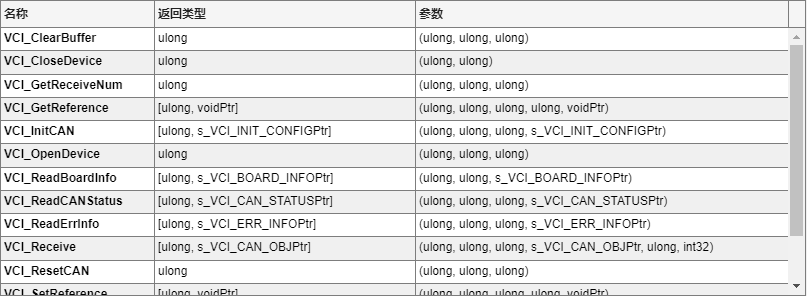

libfunctionsview ControlCAN

calllib('ControlCAN','VCI_OpenDevice',4,0,0)

ans = 1

[a,b] = calllib('ControlCAN','VCI_InitCAN',4,0,0,InitConfig)

a = 1

b = 包含以下字段的 struct :
     AccCode: 0
     AccMask: 4.2950e+09
    Reserved: 0
      Filter: 1
     Timing0: 1
     Timing1: 28
        Mode: 0


[a1,b1] = calllib('ControlCAN','VCI_ReadBoardInfo',4,0,BoardInfo)

a1 = 1

b1 = 包含以下字段的 struct :
        hw_Version: 256
        fw_Version: 272
        dr_Version: 256
        in_Version: 257
           irq_Num: 0
           can_Num: 2
    str_Serial_Num: [49 50 48 49 48 48 55 48 50 48 53 0 0 0 0 0 0 0 0 0]
       str_hw_Type: [85 83 66 67 65 78 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
          Reserved: [0 0 0 0]


[state,ErrInfo] = calllib('ControlCAN','VCI_ReadErrInfo',4,0,0,ErrInfo)

state = 1

ErrInfo = 包含以下字段的 struct :
            ErrCode: 0
    Passive_ErrData: [0 0 0]
     ArLost_ErrData: 0


calllib('ControlCAN','VCI_StartCAN',4,0,0)

ans = 1

%calllib('ControlCAN','VCI_ResetCAN',4,0,0)
%(ulong, ulong, ulong, s_VCI_INIT_CONFIGPtr)
calllib('ControlCAN','VCI_ClearBuffer',4,0,0)

ans = 1

calllib('ControlCAN','VCI_GetReceiveNum',4,0,0)

ans = 0


CanObj1 = libpointer('s_VCI_CAN_OBJPtr',CanObj);
%(ulong, ulong, ulong, s_VCI_CAN_OBJPtr, ulong, int32)
        

[a2,CanObj1]= calllib('ControlCAN','VCI_Receive',4,0,0,CanObj1,1,400)

a2 = 0

CanObj1 = 包含以下字段的 struct :
            ID: 256
     TimeStamp: 0
      TimeFlag: 0
      SendType: 0
    RemoteFlag: 0
    ExternFlag: 0
       DataLen: 8
          Data: [0 0 0 0 0 0 0 0]
      Reserved: [0 0 0]


%calllib('ControlCAN','VCI_Transmit',4,0,0,CanObj,1)

calllib('ControlCAN','VCI_CloseDevice',4,0)

ans = 1

unloadlibrary ControlCAN

libisloaded ControlCAN

ans = logical
   0
